## **MPEG-Layer 2**

0- we need to read the input signal using audioread built-in function, and plot the input signal.

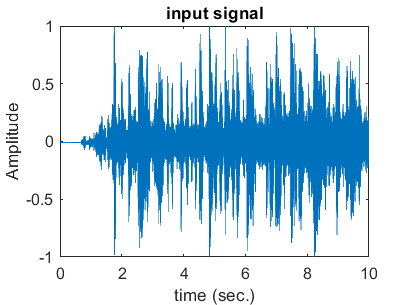

clc
clear all
[signal,Fs] = audioread("listen-to-the-ancient-egyptions-tv.wav");

dt = 1/Fs;
t = 0:dt:(length(signal)*dt)-dt;
plot(t, signal);
title("input signal")
xlabel("time (sec.)")
ylabel("Amplitude")

# Filter Bank

We read the filter coeeficient from the filter.txt file (0:256), then we flipped the coefficients and concatinated to form the 512 coefficients needed for the filter bank implementation.

%reading filter coeffs
M = readmatrix('filters.txt');
M_flipped = M(1:256);
M_flipped = (flip (M_flipped));
Coefs=cat(1,M,M_flipped);


In the following step we initialize the filter bank using the initialized coefficients.

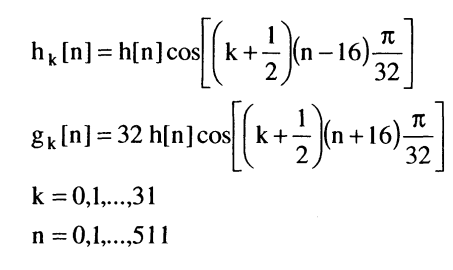

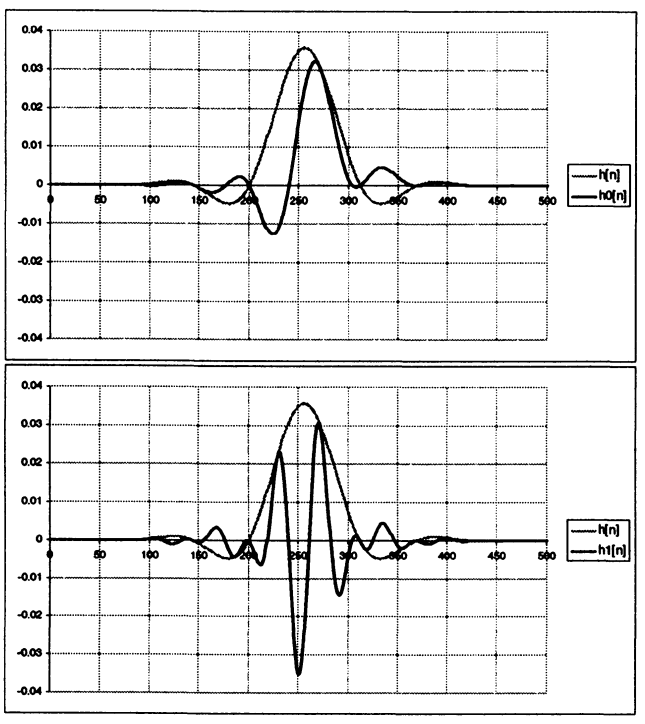

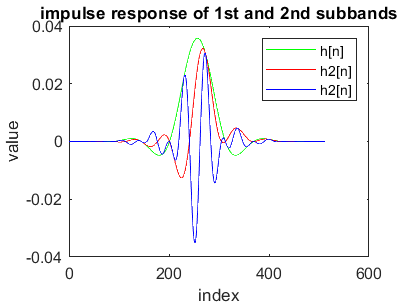

%intializing filter bank
hk=zeros(32,513);
gk=zeros(32,513);

for k = 0:31 
    for n=0:512
        hk(k+1,n+1)=Coefs(n+1)*cos(((k+0.5)*(n-16)*(pi/32)));

    end
end 
for k = 0:31 
    for n=0:512
        gk(k+1,n+1)=32*Coefs(n+1)*cos(((k+0.5)*(n+16)*(pi/32)));

    end
end
figure
plot(1:513,Coefs,'g')
hold on
plot(1:513,hk(1,:),'r')
hold on
plot(1:513,hk(2,:),'b')
legend('h[n]','h2[n]','h2[n]')
title('impulse response of 1st and 2nd subbands');
xlabel('index');
ylabel('value');
hold off

 In this step, we filter the input signal to get 32 subbands each of 240,000, then downsampled by 32 into (32*7,500)

filter_bank_outputs = zeros(32,240000/32);%7500
for k = 0:31 
    filter_bank_outputs(k+1,:)=downsample(filter(hk(k+1,:),1,signal),32) ;
end 

% filter bank 1st subband spectrum

sbband1_spect = abs(fftshift(fft(filter_bank_outputs(1,:), 1024)))

sbband1_spect =     0.2640    0.0784    0.2391    0.2118    0.1950    0.4042    0.2643    0.1711    0.1452    0.4197    0.4943    0.2997    0.4742    0.2923    0.3003    0.6421    0.4004    0.2576    0.7780    0.8963    0.4606    0.4041    0.9867    0.8067    0.1515    0.8316    0.7719    0.4332    0.8697    0.8512    0.3334    0.3875    0.3126    0.3425    0.4068    0.2733    0.5378    0.3449    0.2093    0.4573    0.3490    0.2874    0.3543    0.3366    0.2048    0.7457    0.8122    0.3422    0.2460    0.2313


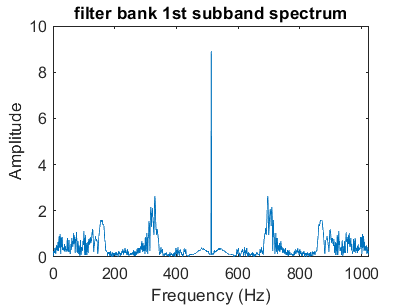


plot(sbband1_spect);
title('filter bank 1st subband spectrum');
xlabel('Frequency (Hz)');
ylabel('Amplitude');

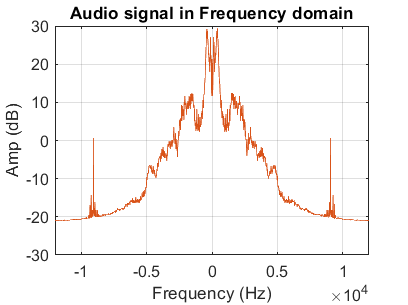

% spectrum of the input signal
fft_size = 1024;
num_frames = floor(length(signal) / fft_size);
spect = zeros(1, fft_size);
k = 0;

for i = 1:num_frames
    w_audio = signal((i - 1) * fft_size + 1 : i * fft_size);
    spect = spect + abs(fftshift(fft(w_audio, fft_size)));
end

spect = spect / num_frames;

f = linspace(-Fs / 2, Fs / 2, fft_size);

figure;
plot(f, 20 * log10(spect));
title('Audio signal in Frequency domain');
xlabel('Frequency (Hz)');
ylabel('Amp (dB)');
grid on;

The following step gets and the plot of the spectrum of the input signal using 1024-point fft (using the provided spectrum file).

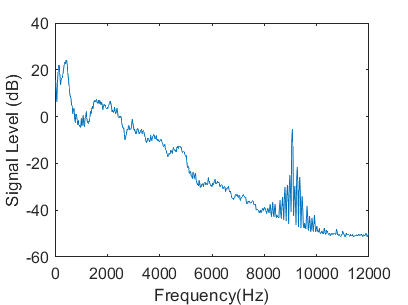

spectrum =cell2mat(struct2cell( load('Signal_Spectrum.mat')));
% my_array = load("Signal_Spectrum.mat", 'my_array');
x= 1:1024;
% plot(x,spectrum);
spectrum2=spectrum(1,513:1024);

plot((1:512)*Fs/1024, mag2db(spectrum2));
xlabel('Frequency(Hz)');
ylabel('Signal Level (dB)');

# Psychoacoustic Model

### Pyschoacoustic part 1

- We initializes arrays `LK`, `A`, and `fk` to store calculated loudness, hearing threshold, and frequency values, respectively.

- We then loop through each frequency bin, calculates the loudness using a psychoacoustic model, and compares it to the hearing threshold.

- If the loudness is below the hearing threshold, it is set to 0.

- We then plots the hearing threshold and the psychoacoustic model with inaudible removal.

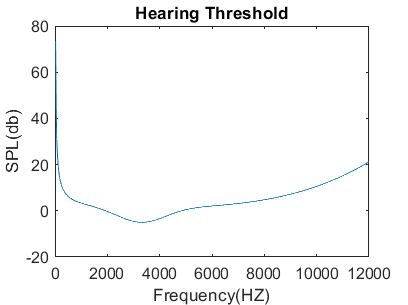

%pyschoacoustic part1
LK=zeros (1,512);
A=zeros (1,512);
fk=zeros(1,512);
% for k=1:512
%     val=(8/3)*(4/(1024^2));
%     LK(k)=96+10*log10(val * spectrum2(k)^2);
%     fk(k)=k * Fs / 1024;
%     A(k)=threshold_of_quite(fk(k));
%     if LK(k)<A(k)
%         LK(k)=0;
%     end 
% end 
for k=1:512
    val=(8/3)*(4/(1024^2));
    LK(k)=96+10*log10(val * spectrum2(k)^2);
    fk(k)=k * Fs / 1024;
    A(k)=threshold_of_quite(fk(k));
end 

%Plotting hearing threshold
figure;
plot(fk,A);
title('Hearing Threshold');
xlabel('Frequency(HZ)');
ylabel('SPL(db)');

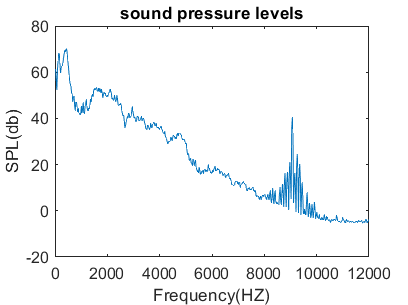


%Plotting SPLS
figure;
plot(fk,LK);
title('sound pressure levels');
xlabel('Frequency(HZ)');
ylabel('SPL(db)');

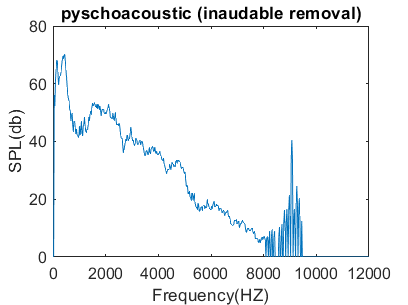

for k=1:512
        if LK(k)<A(k)
        LK(k)=0;
        end
end 




figure;
plot(fk,LK);
title('pyschoacoustic (inaudable removal)');
xlabel('Frequency(HZ)');
ylabel('SPL(db)');

### Pyschoacoustic part 2

- We initializes variables to store the original loudness values (`SPLS`), global masking thresholds (`masking_threshold_global`), and the number of local maskers for each 16-bin group (`locals`).

- We then iterate through each 16-bin group and identifies the global and local maskers in each group.

- The global masker is removed along with its associated frequency bin, and the number of local maskers for each group is stored.

- The local maskers are then removed along with their associated frequency bins.

- The resulting psychoacoustic model with non-tonal removal is plotted.

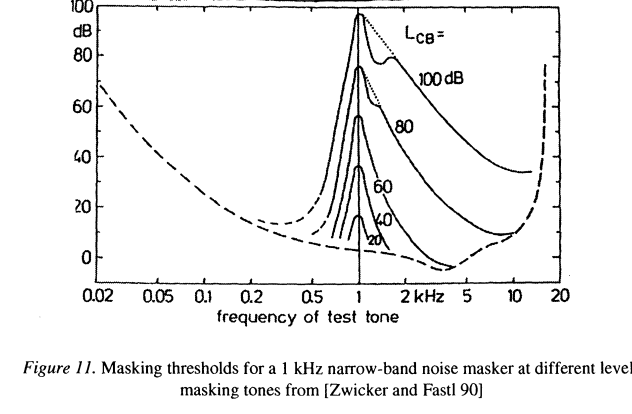

%pyschoacoustic part2

SPLS=LK

SPLS =          0   56.0346   52.4889   60.8505   65.0221   68.1871   67.8572   64.0279   59.6446   61.9208   62.5920   62.7029   64.1634   66.3708   68.2824   69.4292   68.8269   70.1209   70.0547   67.9199   64.6587   62.0976   58.9225   56.0485   54.7868   53.8726   51.1547   50.5573   47.1825   48.9046   49.7552   45.6072   43.4762   47.1908   46.9903   44.7957   42.7806   44.2815   42.3369   42.1767   41.4054   41.8385   45.2982   42.2413   44.0697   46.8267   42.5260   41.9356   45.3011   46.0320


% spls_reshaped=reshape(LK,32,16, []);
masking_threshold_global=zeros(32,1);
locals=[]


locals =

     []



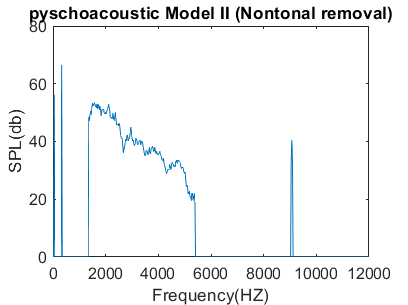

for k=0:31
    
    [gloabl_masker,global_index] =max(LK(1,(k*16+1):(k+1)*16));
    [local_maskers, local_indices] = findpeaks(LK(1,(k*16+1):(k+1)*16));
    
    LK=remove_masked(global_index,LK,Fs,k);
    
    num_of_locals = length(local_indices);
    locals=[locals num_of_locals];
    for i = 1:num_of_locals
        LK=remove_masked(local_indices(1,i),LK,Fs,k);
    end
end

figure;
plot(fk,LK);
title('pyschoacoustic Model II (Nontonal removal)');
xlabel('Frequency(HZ)');
ylabel('SPL(db)');

The output of the Pyschoacoustic Model is (1*512) then to be reshaped in the following step before the encoder into (32*16)

# Encoder

- The encoder takes subbands (from a filter bank and downsampler), loudness values (LKs), a target bit rate (BPS_signal), and the number of FFT points (N) as input.

- It performs an FFT on the subbands and extracts the magnitude spectrum, considering only positive frequencies.

- It then divides the spectrum into 32 subbands, converts the magnitude spectrum to decibels, and calculates the information content within each subband based on loudness values.

- Bit allocation is performed based on the calculated information content and the target bit rate (BPS_signal).

- The function quantizes the output of the filter bank and downsampler using the Quan function.

- The function returns the maximum and minimum values encountered during quantization, the quantized signal (32*7,500), and the allocated bits for each subband.

reshaped_LKS=transpose(reshape(LK,16,32));
%encoder
[max,min,quantized_signal,subband_bits]=Encoder(filter_bank_outputs,reshaped_LKS,16,1024);

# Decoder

- The decoder takes the parameters necessary for decoding: maximum and minimum values during quantization (`max`, `min`), quantized signal, subband bit allocation (`subband_bits`), and the synthesis filter bank coefficients (`gk`).

- It dequantizes the quantized signal using the `DeQuan` function, which performs the inverse of the quantization operation.

- The dequantized signals are then upsampled and filtered using the synthesis filter bank coefficients for each subband.

- The final reconstructed signal restored_signal is obtained by summing the filtered subbands after upsampled to (32*270,000).

So, we manage to reconstruct the signal (1*270,000).

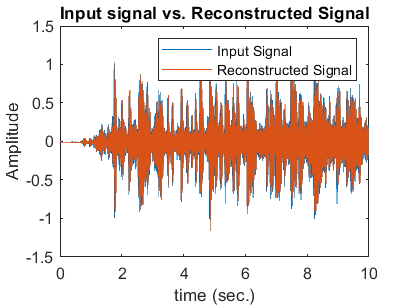

%decoder
restored_signal = decoder(max,min,quantized_signal,subband_bits,gk);

plot(t, signal, t, restored_signal);
title("Input signal vs. Reconstructed Signal");
xlabel("time (sec.)");
ylabel("Amplitude");
legend("Input Signal", "Reconstructed Signal")


audiowrite('output_signla.wav', restored_signal, Fs);

The plot of "Input signal vs. Reconstructed Signal" shows that the reconstructed signal is almost the same as the input signal.

# Compression Ratio

BPS = 16;
% Calculate the original data size
original_data_size = numel(signal) * BPS;

% Calculate the quantized data size
quantized_data_size = 0;

for i = 1:32
    quantized_data_size= quantized_data_size + numel(quantized_signal(i,:)) * subband_bits(i);
end

% Calculate the compression ratio
compression_ratio = round(original_data_size / quantized_data_size);

% Display the compression ratio
disp(['Compression Ratio: ' num2str(compression_ratio) ':1']);

Compression Ratio: 4:1


# References

- Audio Information Processing, TUM, Bernhard Seeber [@audioinformationprocessing]. (n.d.). Psychoacoustics lessons. Youtube. Retrieved December 11, 2023, from [https://www.youtube.com/playlist?list=PLPUcky2a9KhDzRbMu1l5flz3oO_4NxmCS](https://www.youtube.com/playlist?list=PLPUcky2a9KhDzRbMu1l5flz3oO_4NxmCS)

- D. Pan, "A tutorial on MPEG/audio compression," in IEEE MultiMedia, vol. 2, no. 2, pp. 60-74, Summer 1995, doi: 10.1109/93.388209.

- M. Bosi and R. E. Goldberg, Introduction to Digital Audio coding and standards. 2003. doi: 10.1007/978-1-4615-0327-9.

# Team Members

- Muahammad Essam Khattab[a], 202001411

- Mahmoud El-Bahnasawi[a], 202000985

- Ahmed Saber[a], 202001131

- Yahya Mohamed[a], 202000776

- Mario Youchia[a], 201902086

[a]Communications and Information Engineering, UST at Zewail City of Science, Technology, and Innovation, 6th of October City, Giza, Egypt.